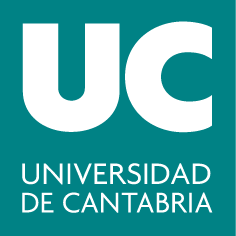

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 1: Integral Doble. Sumas de Riemann**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Calcular integrales dobles mediante sumas de Riemann.

- Calcular integrales dobles exactas de forma simbólica.

### Resumen teórico

#### Suma de Riemann

Llamamos suma de Riemann de la función $f(x,y)$ definida en el rectángulo $R$ para la partición $\lbrace R_{k}\rbrace_{k=1}^{p}$ a la suma:


$$\displaystyle  \sum_{k=1}^{p} f(x_{k}, y_{k})\Delta A_{k} $$


donde $(x_{k},y_{k})$ es un punto cualquiera tomado en el subrectángulo $$R_{k}$$ y $\Delta A_{k}$es el área de  $$R_{k}$$.

Si la partición es regular con $m, n$ particiones en cada dirección respectivamente, entonces: $\Delta A_{k}= \Delta x \Delta y$ con $\Delta x=\frac{x_{final}-x_{inicial}}{m}$, $\Delta y=\frac{y_{final}-y_{inicial}}{n}$

Si tomamos $(x_{i},y_{j})$ como el punto medio de cada celda, que es donde suele obtenerse la mejor aproximación para la mayoría de las funciones:

$x_{i}=x_{inicial}+\frac{\Delta x}{2} + (i-1)\Delta x = x_{inicial}+\Big( i - \frac{1}{2}\Big) \Delta x$     con $i=1,2,3,...,m$

$y_{j}=y_{inicial}+\frac{\Delta y}{2} + (j-1)\Delta y = y_{inicial}+\Big( j - \frac{1}{2}\Big) \Delta y$     con $j=1,2,3,...,n$

#### Integral doble

Sea $f$ una función de dos variables definida sobre un rectángulo cerrado $R$ . Si para toda partición de $R$, tal que la norma de la partición tiende a cero ($\mid\mid R \mid \mid \rightarrow 0$, entonces el número de particiones tiende a infinito), existe el límite:


$$\displaystyle \lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k})\Delta A_{k}\Big)$$


 se dice que $f$** es integrable en **$R$.

Además, el valor de este límite es la integral doble de $f$ sobre $R$ y se denota por:


$$\displaystyle \int\int_{R}f(x,y) dx dy=\lim_{p\to\infty} \Big( \sum_{k=1}^{p} f(x_{k}, y_{k})\Delta A_{k}\Big)$$


### Comandos útiles

#### Comandos para sumar elementos de una matriz o vector

- `sum(A): `Si A es un vector suma sus componentes. Si A es una matriz, devuelve un vector fila con la suma de las filas o columnas de A especificadas. Ejemplo:

A=ones(3,3);
sum(A(1:2,:))

- `sum(A(:)):` suma todos los elementos de la matriz A. Ejemplo:

sum(A(:))

#### Comandos para calcular de forma exacta la integral de una función sobre un intervalo cerrado

- `syms x`: Crea la variable simbólica `x`.

- `int(f, x, a, b)`: para calcular la integral definida de la función f(x) en el intervalo [a,b]. 

- `int(int(f(x,y), y, phi1(x), phi2(x)), x, a, b)`: para calcular la integral doble:


$$\int_{a}^{b}\int_{\phi_{1}(x)}^{\phi_{2}(x)} f(x,y) dy dx$$


- `double(x): `Convierte a decimal con doble precisión los valores recogidos en x, que puede ser una matriz o vector de valores. 

#### Comandos para crear una función

- `function [out1, out2, ...] = funname(in1, in2, ...)` Crea una función de nombre `funname`, con unos parámetros de entrada `(in1,in2,…) `y unas variables de salida `(out1, out2,…). `Se debe guardar la función en un fichero llamado `funname.m. `

#### Comandos para hacer ejecutable una cadena de caracteres

- `inline('expresion')`: construye una función en línea a partir de la expresión indicada. Ejemplo:

g = inline('t^2');
g(8)

- `vectorize(f):` vectoriza la fórmula de la función que aparece en el argumento de entrada.

- `str2sym(f)`: convierte en formato simbólico una cadena de caracteres que se puede ejecutar con el comando `subs`. Ejemplo:

syms f(t)
f=str2sym('t^2');
double(subs(f, 8))

###  Ejercicio resuelto

- **Sumas dobles de Riemann**

Considera la función $z=e^{-(x^{2}+y^{2})}$ .	

a) Representa gráficamente la superficie en el dominio $[-2,2]\times[-2,2]$	

b) Aproxima el valor de la integral $I=\int\int_{R}e^{-(x^2+y^2)} dx dy$ en el dominio $R=[0,2]\times [0,2]$, utilizando las sumas de Riemann en el punto medio para una partición de 8 subintervalos en cada eje. 

c) Crea una función de Matlab que permita obtener las sumas de Riemann. Los argumentos de entrada serán la función, el dominio y el número de particiones ($m$ particiones en el eje X y $n$ particiones en el eje Y).

d) Usando la función anterior, repite la aproximación tomando particiones de 16 y 20 subintervalos en cada eje. Compara las aproximaciones obtenidas.

e) Calcula con Matlab el valor exacto de la integral. Compara el resultado con las aproximaciones calculando el error cometido.

a) Representa gráficamente la superficie en el dominio $[-2,2]\times[-2,2]$	

x=-2:0.1:2; y=x;
[X,Y]=meshgrid(x,y);
Z=exp(-(X.^2+Y.^2));
figure(1),
surf(X,Y,Z)
xlabel ('Eje X'); ylabel ('Eje Y'); zlabel('Eje Z'), title ('f(x)=exp(-(x^2+y^2))')

b) Aproxima el valor de la integral $I=\int\int_{R}e^{-(x^2+y^2)} dx dy$ en el dominio $R=[0,2]\times [0,2]$, utilizando las sumas de Riemann en el punto medio para una partición de 8 subintervalos en cada eje. 

A modo de ejemplo, se desarrolla el razonamiento teórico que servirá para entender el código posterior.

La suma de Riemann que aproxima la integra tomando una partición en $m\times n$ celdas es:

$S=\displaystyle\sum_{i=1}^{m}\sum_ {j=1}^{n}f(x_{i}, y_{j})\Delta x \Delta y= \frac{4}{m n}\sum_{i=1}^{m}\sum_ {j=1}^{n}f(x_{i}, y_{j})$             pues     $\Delta x=\frac{x_{final}-x_{inicial}}{m}=\frac{2}{m}, \Delta y=\frac{y_{final}-y_{inicial}}{n}=\frac{2}{n}$

En este caso los puntos medios de las celdas son:

$x_{i}= x_{inicial}+\Big( i - \frac{1}{2}\Big) \Delta x= \Big( i - \frac{1}{2}\Big) \frac{2}{m}$         con $i=1,2,3,...,m$

$y_{j}=y_{inicial}+\Big( j - \frac{1}{2}\Big) \Delta y= \Big( j - \frac{1}{2}\Big) \frac{2}{n}$         con $j=1,2,3,...,n$

Para el caso de 8 subintervalos $m=n=8$, $\Delta x=\Delta y=\frac{2}{8}=\frac{1}{4}$ y los puntos centrales de las celdas son:


$$x_{i}=\frac{1}{8}, \frac{3}{8}, \frac{5}{8}, \frac{7}{8}, \frac{9}{8}, \frac{11}{8}, \frac{13}{8}, \frac{15}{8}$$
     
$$y_{j}=\frac{1}{8}, \frac{3}{8}, \frac{5}{8}, \frac{7}{8}, \frac{9}{8}, \frac{11}{8}, \frac{13}{8}, \frac{15}{8}$$


La suma de Riemann para esa partición será:


$$S=\displaystyle\frac{1}{16}\sum_{i=1}^{8}\sum_ {j=1}^{8}f(x_{i}, y_{j})= \frac{1}{16}\Big[f\Big(\frac{1}{8},\frac{1}{8}\Big)+f\Big(\frac{1}{8},\frac{3}{8}\Big)+...+f\Big(\frac{1}{8},\frac{15}{8}\Big)+f\Big(\frac{3}{8},\frac{1}{8}\Big)+f\Big(\frac{3}{8},\frac{3}{8}\Big)+...+f\Big(\frac{3}{8},\frac{15}{8}\Big)+...+f\Big(\frac{15}{8},\frac{1}{8}\Big)+f\Big(\frac{15}{8},\frac{3}{8}\Big)+...+f\Big(\frac{15}{8},\frac{15}{8}\Big)\Big]$$


a=0;b=2;c=0;d=2;
m=8;n=8;
%incrementos de x e y en la partición
inc=[(b-a)/m,(d-c)/n];
%coordenadas x de los puntos medios
x=a+inc(1)/2:inc(1):b-inc(1)/2;
%coordenadas y de los puntos medios
y=c+inc(2)/2:inc(2):d-inc(2)/2;
%coordenadas de los puntos medios de la malla o partición
[X,Y]=meshgrid(x,y);
%valor de la función que integramos en los puntos medios de la %malla
Z=exp(-X.^2-Y.^2);
format long
%cálculo de la suma de Riemann que aproxima la integral doble
volumen_aproximado=sum(Z(:))*inc(1)*inc(2)

c) Define una función de Matlab que permita obtener las sumas de Riemann. Los argumentos de entrada serán la función, el dominio y el número de particiones ($m$ particiones en el eje X y $n$ particiones en el eje Y).

El código para el caso anterior se puede generalizar fácilmente, incluyendo el dominio y el número de particiones y creando una función en línea a partir de una cadena de caracteres que representa la función. El archivo `sumaRiemann2.m` deberá encontrarse en el directorio de trabajo para ser ejecutado desde otro programa.

d) Usando la función anterior, repite la aproximación tomando particiones de 16 y 20 subintervalos en cada eje. Compara las aproximaciones obtenidas.

suma_Riemann8=sumaRiemann2('exp(-x^2-y^2)',0,2,0,2,8,8)
suma_Riemann16=sumaRiemann2('exp(-x^2-y^2)',0,2,0,2,16,16)
suma_Riemann20=sumaRiemann2('exp(-x^2-y^2)',0,2,0,2,20,20)

e) Calcula con Matlab el valor exacto de la integral. Compara el resultado con las aproximaciones calculando el error cometido.

syms u v
valor_exacto=double(int(int(exp(-u^2-v^2),u,0,2),v,0,2))
error8=abs(valor_exacto-suma_Riemann8) %error para n=m=8
error16=abs(valor_exacto-suma_Riemann16) %error para n=m=16
error20=abs(valor_exacto-suma_Riemann20) %error para n=m=20